% ----------------- %
% Projet 1 SLAM EKF %
% ----------------- %

clear all; close all;


## Creation de la carte

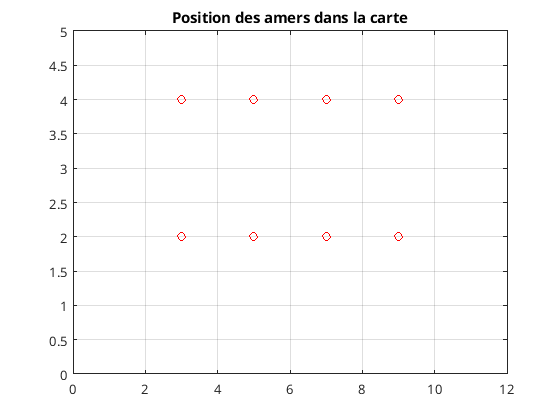

%Distances entre les amers
distXamer = 2;
disYamer = -2;

%Position des amers, vecteur de position des amers :
%    - elements impairs : position en X de l'amer 2*i-1
%    - elements pairs : position en Y de l'amer 2*i
amer=[3 ;4];

for i=2:4
    amer(2*i-1) = amer(2*i-3)+distXamer;
    amer(2*i) = amer(2);
end
for i=5:8
    amer(2*i-1) = amer(2*i-9);
    amer(2*i) = amer(2)+disYamer;
end
%Affichage des amers
figure(1)
plot(amer(1:2:16), amer(2:2:16), 'or')
grid on 
axis([0 12 0 5])
title("Position des amers dans la carte")

## Génération des données réelles

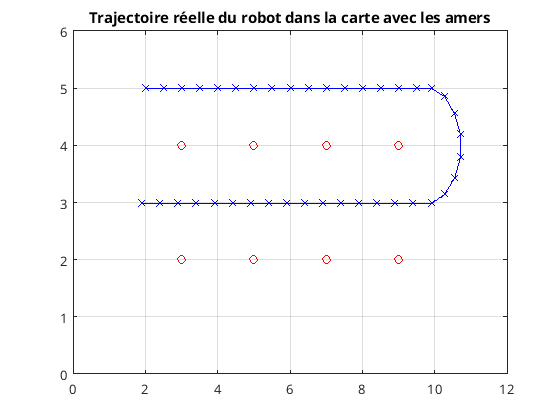

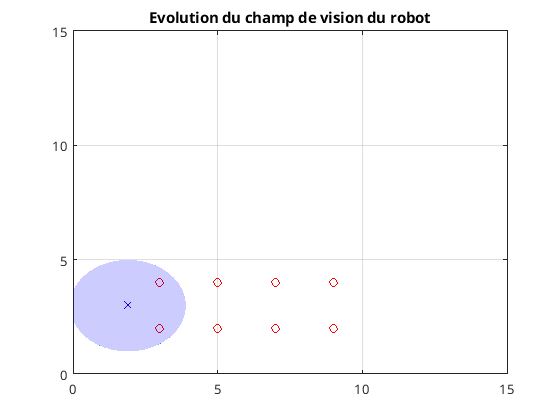

%Nombre d'instants
N1 = 15;
N2 = 8;
N3 = 17;
N = N1+N2+N3;

%Genération de la position du robot 
%Position initiale
Xr(:,1) = [2;5;0];
%Vecteur de commande
for i=1:N1
    U(:,i)=[0.5;0;0];
end
for i=N1+1:N1+N2
    U(:,i)=[0.4;0;-pi/N2];
end
for i=N1+N2+1:N1+N2+N3
    U(:,i)=[0.5;0;0];
end
%Boucle de generation de la trajectoire
for i=2:N
    Xr(:,i)=Xr(:,i-1)+[U(1,i-1)*cos(Xr(3,i-1))-U(2,i-1)*sin(Xr(3,i-1)) ; U(1,i-1)*sin(Xr(3,i-1))+U(2,i-1)*cos(Xr(3,i-1)) ; U(3,i-1)];
end

%Affichage de la trajectoire du robot 
figure(2)
plot(amer(1:2:16), amer(2:2:16), 'or')
hold on
plot(Xr(1,:), Xr(2,:), 'x-b')
axis([0 12 0 6])
grid on
title("Trajectoire réelle du robot dans la carte avec les amers")

%Generation des mesures
distVision = 2;
%Pas de mesures a l'etat initial 
z(:,1) = NaN * ones(2*8,1);

%Genrations de mesures pour les instants 2 a N
for k=2:N
    for j=1:8
        z(2*j-1,k) = sqrt((amer(2*j-1)-Xr(1,k))^2+(amer(2*j)-Xr(2,k))^2);
        z(2*j,k) = atan2((amer(2*j)-Xr(2,k)),(amer(2*j-1)-Xr(1,k)))-Xr(3,k);
    end
end

%Suppression des données hors du champ de vision 
for k=2:N
    for j=1:8
        if(z(2*j-1,k)>distVision)
            z(2*j-1,k) = NaN;
            z(2*j,k) = NaN;
        end
    end
end
%Affichage du champ de vision
for k=1:N
    figure(3)
    plot(amer(1:2:16), amer(2:2:16), 'or');
    grid on
    hold on 
    axis([0 15 0 15]);
    plot(Xr(1,k), Xr(2,k), 'xb');
    cercle(Xr(1:2,k), distVision, 'b');
    hold off
    title('Evolution du champ de vision du robot')
    drawnow
    pause(0.5)
end

## Filtrage

## Affichage des données